% SIMULATION USED FOR SHOWING COULOMB'S LAW
% USING MESH FUNCTION INSTEAD OF FOR LOOPS

% This program is a significant improvement and was worked on over the
% course of the day. The implementation of meshgrid gave the code the
% effiency it needed to cut down on calculations.

tic

% Constants %
cou_cont = 8.9876e9 % N*m^2/C^2

cou_cont = 8.9876e+09

electron_q = -1.6021765e-19 % C

electron_q = -1.6022e-19

proton_q = 1.6021765e-19    % C

proton_q = 1.6022e-19

F = 1.5;

Low_bound = -6;
Max_bound = 10;
n_elements = 30;

% Whole Coordinate Plane %
X = linspace(Low_bound,Max_bound,n_elements)

X =    -6.0000   -5.4483   -4.8966   -4.3448   -3.7931   -3.2414   -2.6897   -2.1379   -1.5862   -1.0345   -0.4828    0.0690    0.6207    1.1724    1.7241    2.2759    2.8276    3.3793    3.9310    4.4828    5.0345    5.5862    6.1379    6.6897    7.2414    7.7931    8.3448    8.8966    9.4483   10.0000


size_plot = size(X,2);

dist = 0;

% Electron Coords %
x_e = randi([Low_bound + 1 Max_bound - 1]);
y_e = randi([Low_bound + 1 Max_bound - 1]);


% Proton Coords %
x_p = randi([Low_bound + 1 Max_bound - 1]);
y_p = randi([Low_bound + 1 Max_bound - 1]);


% % PERM COORDS %
% x_p = 5;
% y_p = 5;
% 
% x_e = 10;
% y_e = 10;

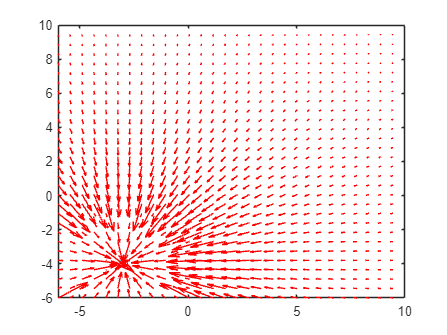

% ELECTRON FIGURE %

plot(x_e,y_e,'o')  % empty figure to be filled from for loop
hold on

[X,Y] = meshgrid(X,X);  % Create matrixes for points

comp_X = zeros(size(X));    % Pre-make the component matrixes
comp_Y = zeros(size(X));

% plot(X,Y,'*')

for i = 1:size_plot - 1     % This generates the components of vectors
    for j = 1:size_plot - 1

     comp_X(i,j) = X(i,j) - x_e;
     comp_Y(i,j) = Y(i,j) - y_e;

    end
end

r = r_dist( comp_X , comp_Y );

e_force = Coulombs_force(electron_q,r,cou_cont).*10^9;

% Unit Vectors %
U = (comp_X./r).*e_force*(F);    % F is some factor that helps generate longer arrows
V = (comp_Y./r).*e_force*(F);

for i = 1:size_plot - 1             % Tries to keep arrows from being too big
    for j = 1:size_plot - 1
        if( U(i,j)^2 + V(i,j)^2 > 5)
         U(i,j) = U(i,j)*.001;
         V(i,j) = V(i,j)*.001;
        end
        if( U(i,j)^2 + V(i,j)^2 < .03)
         U(i,j) = U(i,j)*10 ;
         V(i,j) = V(i,j)*10;
        end
    end
end

quiver(X,Y,U,V,0,'r')

hold off

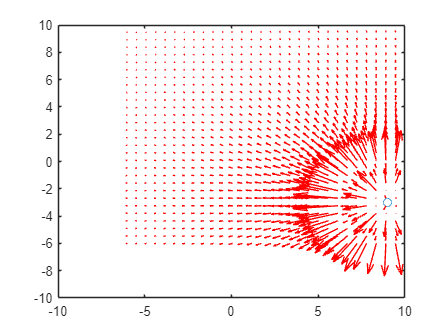

% PROTON FIGURE %

plot(x_p,y_p,'o')  % empty figure to be filled from for loop
hold on

comp_X = zeros(size(X));    % Pre-make the component matrixes
comp_Y = zeros(size(X));

% plot(X,Y,'*')

for i = 1:size_plot - 1     % This generates the components of vectors
    for j = 1:size_plot - 1

     comp_X(i,j) = X(i,j) - x_p;
     comp_Y(i,j) = Y(i,j) - y_p;

    end
end

r = r_dist( comp_X , comp_Y );

e_force = Coulombs_force(proton_q,r,cou_cont).*10^9;

% Unit Vectors %
U = (comp_X./r).*e_force*(F);    % F is some factor that helps generate longer arrows
V = (comp_Y./r).*e_force*(F);

for i = 1:size_plot - 1             % Tries to keep arrows from being too big
    for j = 1:size_plot - 1
        if( U(i,j)^2 + V(i,j)^2 > 5)
         U(i,j) = U(i,j)*.001;
         V(i,j) = V(i,j)*.001;
        end
        if( U(i,j)^2 + V(i,j)^2 < .0859)
         U(i,j) = U(i,j)*10 ;
         V(i,j) = V(i,j)*10;
        end
    end
end

quiver(X,Y,U,V,0,'r')

hold off

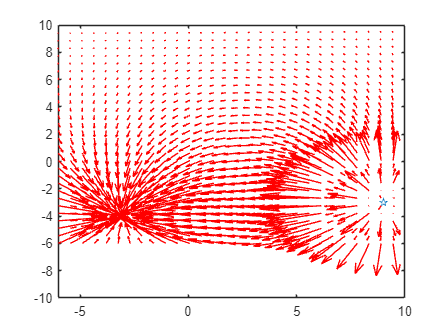

% % Both in same graph %

plot(x_p,y_p,"penta")
hold on
plot(x_e,y_e,'o')

comp_X_p = zeros(size(X));    % Pre-make the components for proton
comp_Y_p = zeros(size(X));

comp_X_e = zeros(size(X));    % Pre-make the components for electron
comp_Y_e = zeros(size(X));

% plot(X,Y,'*')

for i = 1:size_plot - 1     % This generates the components of vectors
    for j = 1:size_plot - 1

        comp_X_p(i,j) = X(i,j) - x_p;
        comp_Y_p(i,j) = Y(i,j) - y_p;
    
        comp_X_e(i,j) = X(i,j) - x_e;
        comp_Y_e(i,j) = Y(i,j) - y_e;

    end
end

r_p = r_dist( comp_X_p , comp_Y_p ); % Get distance between points for unit vectors
r_e = r_dist( comp_X_e , comp_Y_e );

e_force_p = Coulombs_force(proton_q,r_p,cou_cont) * 10^9;
e_force_e = Coulombs_force(electron_q,r_e,cou_cont) * 10^9;

Tot_X_comp = ((comp_X_p./r_p).*(e_force_p) + (comp_X_e./r_e).*(e_force_e))*(F);
Tot_Y_comp = ((comp_Y_p./r_p).*(e_force_p) + (comp_Y_e./r_e).*(e_force_e))*(F);

% Unit Vectors %
U = (Tot_X_comp);
V = (Tot_Y_comp);

for i = 1:size_plot - 1             % Tries to keep arrows from being too big
    for j = 1:size_plot - 1
        if( U(i,j)^2 + V(i,j)^2 > 5)
         U(i,j) = U(i,j)*.001;
         V(i,j) = V(i,j)*.001;
        end
        if( U(i,j)^2 + V(i,j)^2 < .0859)
         U(i,j) = U(i,j)*10 ;
         V(i,j) = V(i,j)*10;
        end
    end
end

quiver(X,Y,U,V,0,'r','filled')

hold off


toc

Elapsed time is 0.348483 seconds.


function e_force = Coulombs_force(x,dist,k)    % Calculates E_field force
    e_force = k .* ( x ./ dist.^2 );
end

function r = r_dist(x,y)    % Calculates distance from charged source to point
    r = sqrt( x.^2 + y.^2);
end
